out

out =   Simulink.SimulationOutput:

                   cost: [1x1 timeseries] 
     laneSegmentsCoords: [1x1 timeseries] 
                  lanes: [1x1 struct] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                     mv: [1x1 timeseries] 
             mv_command: [1x1 timeseries] 
                mv_real: [1x1 timeseries] 
                 mv_seq: [1x1 timeseries] 
                  state: [1x1 struct] 
                 status: [1x1 timeseries] 
                      t: [1x1 timeseries] 
                   tout: [732x1 double] 
              waypoints: [1x1 timeseries] 
     waypoints_relative: [1x1 timeseries] 
                  x_seq: [1x1 timeseries] 
                  y_seq: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



i=60;

state_pos=out.state.Position.Data(:,1:2,i);
state_vel=out.state.Velocity.Data(:,1:2,i);
state_ori=out.state.Orientation.Data(:,3,i);

mv_seq=out.mv_seq.Data(:,:,i);
action_i=out.mv.Data(i,:)

action_i =     2.3514   -0.0480


state_i=[0,0,0,state_vel(1)]'

state_i =          0
         0
         0
   23.2989



weights=0;
limits=0;
laneCoords=0;
types=0;
nextState_dynamics = vehicleDynamics_Simple(state_i, action_i, ...
    Ts, L, waypoints, weights, limits, ...
    laneCoords, types)

nextState_dynamics =     2.3299
   -0.0010
   -0.0007
   23.5340



deltaState_pos=out.state.Position.Data(:,1:2,i+1)-out.state.Position.Data(:,1:2,i);
deltaState_ori=out.state.Orientation.Data(:,3,i+1)-out.state.Orientation.Data(:,3,i);
newState_vel=out.state.Velocity.Data(:,1,i+1);
nextState_simulation=[deltaState_pos deltaState_ori newState_vel]'

nextState_simulation =     3.8191
    0.0760
    0.0029
   23.6769


% v=29.3056;
% steer=25;
% 
% beta=atand(tand(steer)/2);
% dyaw=v*cosd(beta)/L*tand(steer);
% yaw_dyn=dyaw*Ts
% 
% beta=atand(tand(rad2deg(steer))/2);
% dyaw=v*cosd(beta)/L*tand(rad2deg(steer));
% yaw_sym=dyaw*Ts


mv_real=out.mv_real.Data;
t_mv_real=out.mv_real.Time

t_mv_real =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


mv_command=out.mv_command.Data;
t_mv_command=out.mv_command.Time

t_mv_command =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


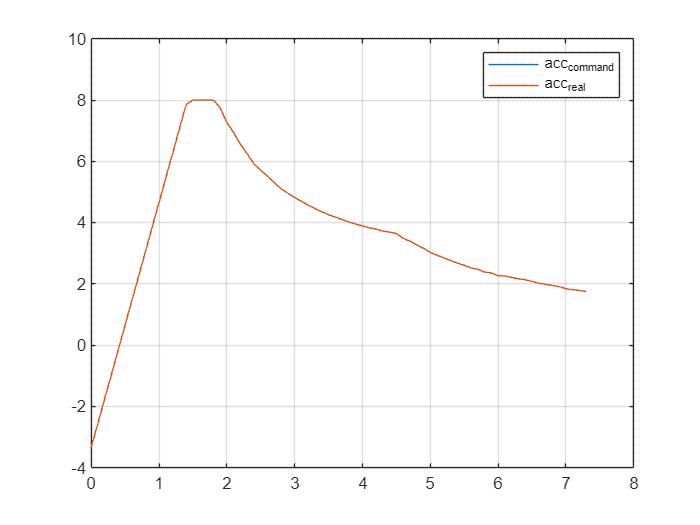


figure
plot(t_mv_command,mv_command(:,1))
hold on
plot(t_mv_real,mv_real(:,1))
grid on
legend('acc_command','acc_real')

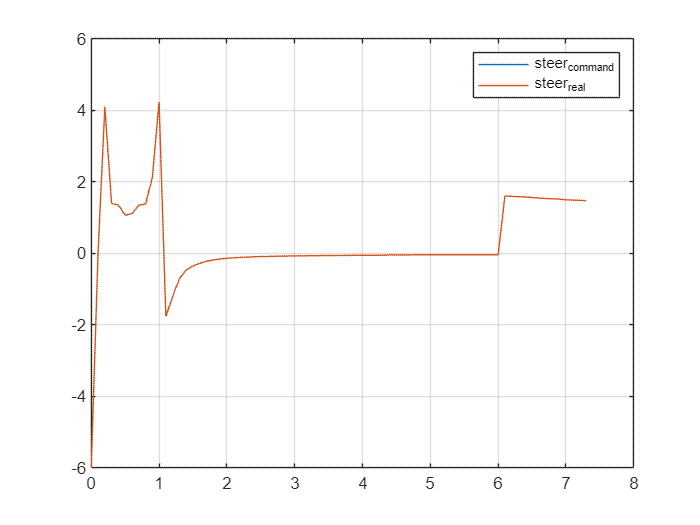


figure
plot(t_mv_command,mv_command(:,2))
hold on
plot(t_mv_real,mv_real(:,2))
grid on
legend('steer_command','steer_real')

v=out.state.Velocity.Data(1,1,:);
v=reshape(v,[size(v,3),1]);
t_v=out.state.Velocity.Time

t_v =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


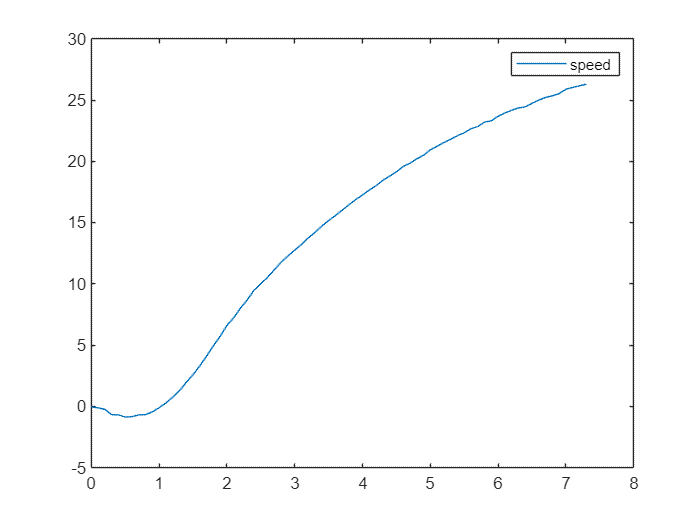

figure
plot(t_v,v)
legend('speed')


laneSegmentCoords=out.laneSegmentsCoords.Data

laneSegmentCoords = laneSegmentCoords(:,:,1) =

        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
        1000        1000
  